1.

A=eye(4,5).*7

A =      7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0


2. 

E=[1 0 0; 0 1 0; 3 0 1]

E =      1     0     0
     0     1     0
     3     0     1


og_matrix = [10 10 2; 2 5 5; 10 9 10]

og_matrix =     10    10     2
     2     5     5
    10     9    10


after_matrix = E*og_matrix

after_matrix =     10    10     2
     2     5     5
    40    39    16


3.

augmented_mat = [og_matrix [1 0 0;0 1 0;0 0 1]]

augmented_mat =     10    10     2     1     0     0
     2     5     5     0     1     0
    10     9    10     0     0     1


rref(augmented_mat)

ans =     1.0000         0         0    0.0175   -0.2867    0.1399
         0    1.0000         0    0.1049    0.2797   -0.1608
         0         0    1.0000   -0.1119    0.0350    0.1049


4.

coff_matrix = [3 4; 5 6]

coff_matrix =      3     4
     5     6


det(coff_matrix)

ans = -2.0000

lll = inv(coff_matrix)*[3;7]

lll =     5.0000
   -3.0000


5.

lll2= coff_matrix\[3;7]

lll2 =     5.0000
   -3.0000


6.

value_pipe = [130 -30 0 500;-90 90 0 0;-40 -60 120 500]

value_pipe =    130   -30     0   500
   -90    90     0     0
   -40   -60   120   500


rref(value_pipe)

ans =     1.0000         0         0    5.0000
         0    1.0000         0    5.0000
         0         0    1.0000    8.3333


7.

f1 = @(x,y) exp(x.*y)-y.^2

f1 = function_handle with value:
    @(x,y)exp(x.*y)-y.^2


f2 = @(x,y) cos(x+y)

f2 = function_handle with value:
    @(x,y)cos(x+y)


fimplicit(f1,[-5,5],'c')
hold on
fimplicit(f2,[-5,5],'r')
legend({"f1","f2"},'Location','southeast')
grid on


roots = []


roots =

     []



g1 = @(x) exp(x(1).*x(2))-x(2).^2

g1 = function_handle with value:
    @(x)exp(x(1).*x(2))-x(2).^2


g2 = @(x) cos(x(1)+x(2))

g2 = function_handle with value:
    @(x)cos(x(1)+x(2))



[x,fx]= fsolve(@nonlin,[-1,-2])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =    -0.3387   -1.2320


fx = 1.0e-07 *

   -0.9755
    0.0000


plot(x(1),x(2),'or','MarkerFaceColor','r','MarkerSize',8)


[x1,fx1]= fsolve(@nonlin,[3,-1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x1 =     2.1254   -0.5546


fx1 = 1.0e-08 *

   -0.1782
   -0.0000


plot(x1(1),x1(2),'or','MarkerFaceColor','r','MarkerSize',8)

[x2,fx2]= fsolve(@nonlin,[2,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x2 =     0.3387    1.2320


fx2 = 1.0e-07 *

   -0.1318
   -0.0000


plot(x2(1),x2(2),'or','MarkerFaceColor','r','MarkerSize',8)

[x3,fx3]= fsolve(@nonlin,[-3,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x3 =    -2.1254    0.5546


fx3 = 1.0e-08 *

   -0.1782
   -0.0000


plot(x3(1),x3(2),'or','MarkerFaceColor','r','MarkerSize',8)

[x4,fx4]= fsolve(@nonlin,[0,4])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x4 =     0.6922    4.0202


fx4 = 1.0e-14 *

   -0.7105
   -0.0184


plot(x4(1),x4(2),'or','MarkerFaceColor','r','MarkerSize',8)

[x5,fx5]= fsolve(@nonlin,[0,-4])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x5 =    -0.6922   -4.0202


fx5 = 1.0e-15 *

         0
    0.7045


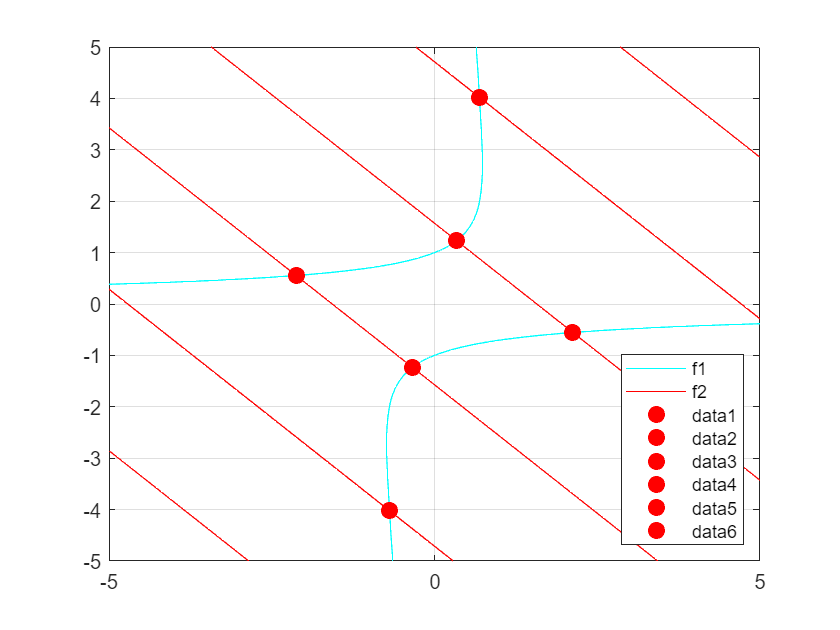

plot(x5(1),x5(2),'or','MarkerFaceColor','r','MarkerSize',8)

hold off

example

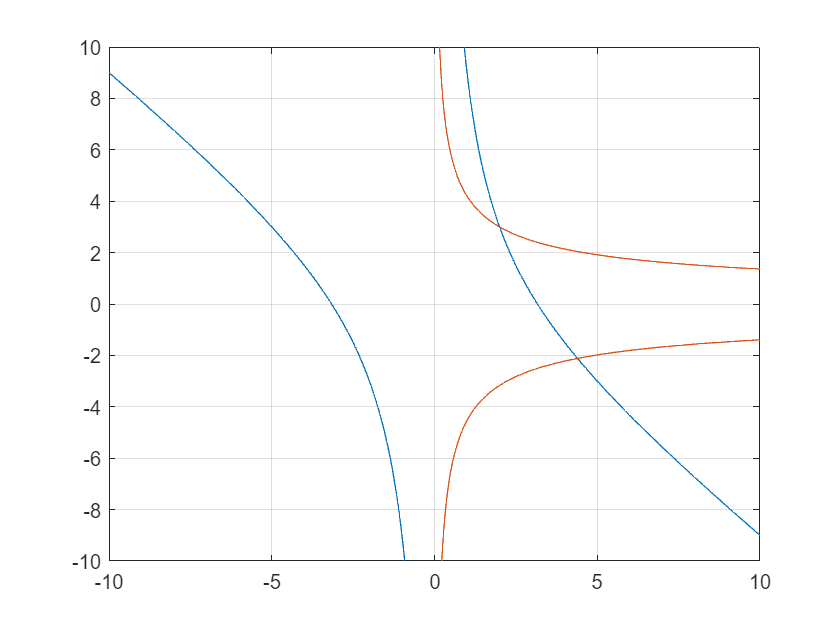

f1 = @(x,y) x.^2+x.*y-10;
f2 = @(x,y) y+3*x.*y.^2-57;

fimplicit(f1,[-10 10])
hold on
fimplicit(f2,[-10 10])
grid on
hold off



[x,fx] = fsolve(@nonlinea1,[4,-2])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     4.3937   -2.1178


fx = 1.0e-14 *

    0.3553
    0.7105


[x,fx] = fsolve(@nonlinea1,[2,4])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     2.0000    3.0000


fx = 1.0e-11 *

   -0.0028
    0.1265


9

v1 = @(x,y) 3*x.^2 + 2*y.^2-25;
fimplicit(v1,[-3,3])
hold on
v2 = @(x,y) 2*x.^2-y-15;
fimplicit(v2,[-3,3])

[x_val,fx_val]=fsolve(@nonlin9,[-2.4,-1.5])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_val =    -2.5929   -1.5542


fx_val = 1.0e-09 *

    0.3692
    0.2457


plot(x_val(1),x_val(2),'or','MarkerFaceColor','r','MarkerSize',8)


[x_val1,fx_val1]=fsolve(@nonlin9,[-2.8,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_val1 =    -2.8111    0.8042


fx_val1 = 1.0e-07 *

    0.1340
    0.0011


plot(x_val1(1),x_val1(2),'or','MarkerFaceColor','r','MarkerSize',8)


[x_val2,fx_val2]=fsolve(@nonlin9,[2.4,-1.5])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_val2 =     2.5929   -1.5542


fx_val2 = 1.0e-09 *

    0.3692
    0.2457


plot(x_val2(1),x_val2(2),'or','MarkerFaceColor','r','MarkerSize',8)


[x_val3,fx_val3]=fsolve(@nonlin9,[2.8,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_val3 =     2.8111    0.8042


fx_val3 = 1.0e-07 *

    0.1340
    0.0011


plot(x_val3(1),x_val3(2),'or','MarkerFaceColor','r','MarkerSize',8)
roots_val = [x_val;x_val1;x_val2;x_val3]

roots_val =    -2.5929   -1.5542
   -2.8111    0.8042
    2.5929   -1.5542
    2.8111    0.8042


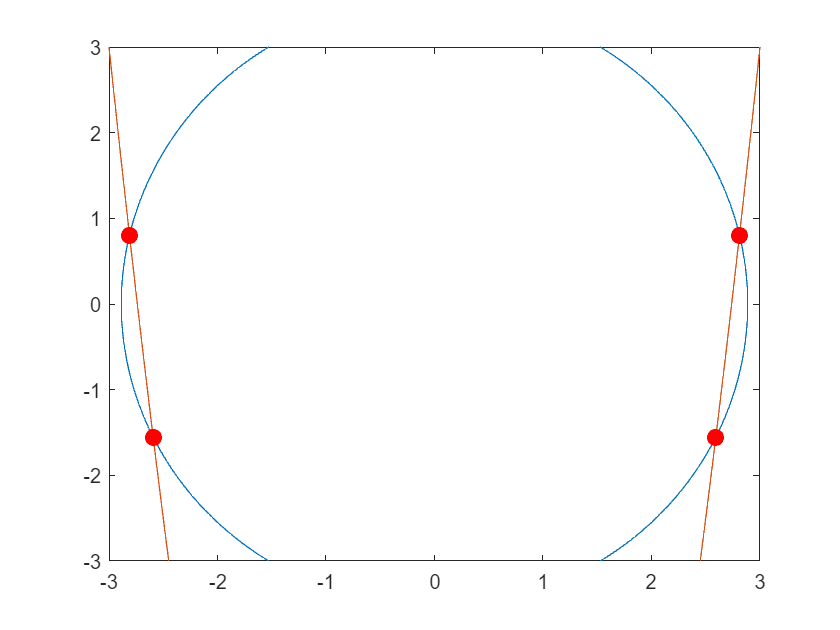


hold off

13

A5=[1 -3 0;0 1 3;2 -10 2];

A5 =      1    -3     0
     0     1     3
     2   -10     2


A_sol = [-5 -1 -20]';

A_sol =     -5
    -1
   -20



x_A5 = A5\A_sol

x_A5 =      1
     2
    -1


function

function f = nonlinea1(x)
f = [x(1)^2+x(1)*x(2)-10; x(2)+3*x(1)*x(2)^2-57];
end

function f=nonlin(x)
f = [exp(x(1).*x(2))-x(2).^2;cos(x(1)+x(2))];
end

function f=nonlin9(x)
f=[3*x(1)^2+2*x(2)^2-25; 2*x(1)^2-x(2)-15];
end